# creating a world map

land = readgeotable("landareas.shp");
bords = readgeotable("C:\Users\eladz\Downloads\world-administrative-boundaries\world-administrative-boundaries.shp");
rivers = readgeotable("worldrivers.shp");
cities = readgeotable("worldcities.shp");

load coastlines

myFigure;
newmap

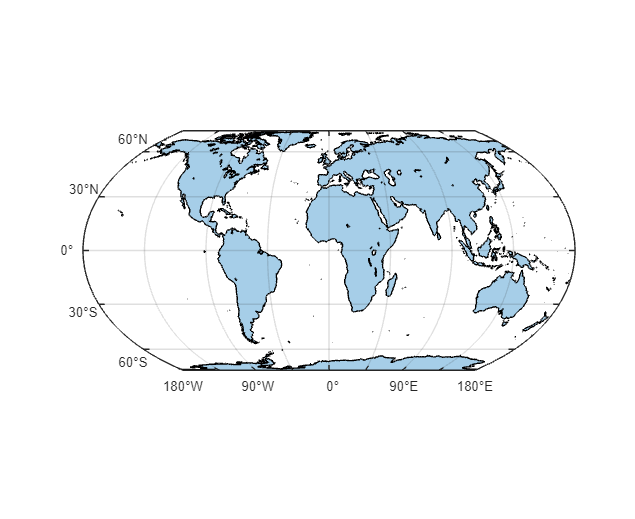


%geoplot(land);

cou_nam = {'Belgium', 'Bulgaria', 'Czech Republic', 'Denmark', 'Germany','Estonia','Ireland',...
    'Greece','Spain','France','Croatia','Italy', 'Cyprus','Latvia', 'Lithuania', 'Luxembourg',...
     'Hungary', 'Malta', 'Netherlands','Austria', 'Poland', 'Portugal','Romania','Slovenia', 'Slovakia',...
        'Finland', 'Sweden'};
numRegions = length(cou_nam);
cmap=colormap;
% Random vector of values (one for each country)
datarange = [-5 5]; % get the actual range of the data
data = range(datarange)*rand(numRegions,1) + min(datarange); % i'm assuming this is a placeholder
coloridx = round(rescale(data,1,size(cmap,1))); % rescale the data to use as an index into cmap


cairo=[30.005,31.237];
tiberias=[32.789,35.525];



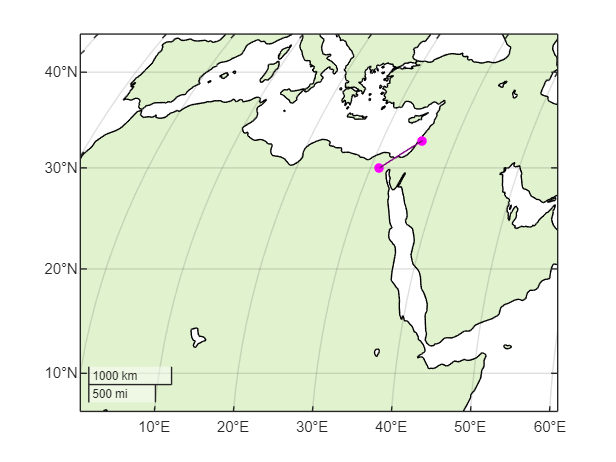


figure
p = projcrs(8859,"Authority","EPSG");
ax=newmap(p);
%xh=worldmap("World");% europe
%ax=axesm
geoplot(land,FaceColor=[0.65 0.85 0.45])
%geoplot(bords,FaceColor=[0.65 0.85 0.45])
geolimits([10 40],[0 50])
hold on
geoplot(cairo(1),cairo(2),"om",MarkerFaceColor="m")
geoplot(tiberias(1),tiberias(2),"om",MarkerFaceColor="m")

[l,g] = gcwaypts(tiberias(1),tiberias(2),cairo(1),cairo(2),20);
geoplot(l,g,'-','color',[.5 0 .5],...
                          'markeredgecolor','r','marker','none');

%annotation("arrow", [0.6893 0.6125], [0.6895 0.6357])

%borders
%borders('countries','facecolor',[0.88 0.95 0.81]) 
%tightmap
%for i = 1:1:numRegions
%  bordersm(,'facecolor','w') 
%end

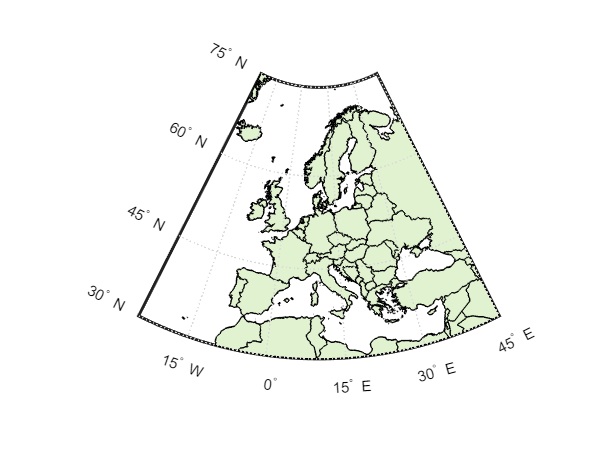

figure;
xh=worldmap('Europe');% europe
setm(xh,'MapProjection','eqaconic')
geoshow(land,"FaceColor",[0.88 0.95 0.81])
hold on
%geoshow(48.8575,2.3514,'DisplayType','multipoint')

bordersm('countries','facecolor',[0.88 0.95 0.81]) 

% for i = 1:1:numRegions
%  bordersm(cou_nam{i},'facecolor',[0.88 0.95 0.81]) 
% end
%([30 60],[-13 43])

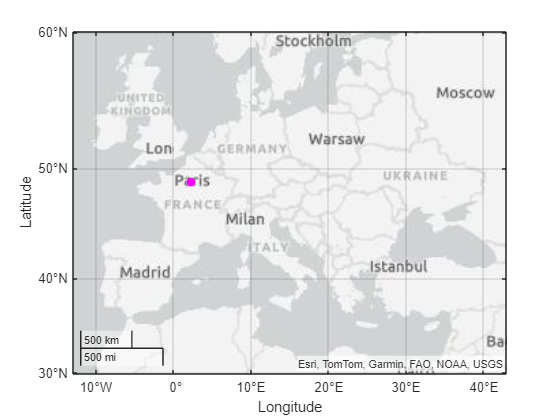


figure

geoplot(48.8575,2.3514)

hold on
geoplot(48.8575,2.3514,"om",MarkerFaceColor="m")
geolimits([30 60],[-13 43])

%geoshow(48.8575,2.3514,'DisplayType','point')
%48.8575° N, 2.3514° E